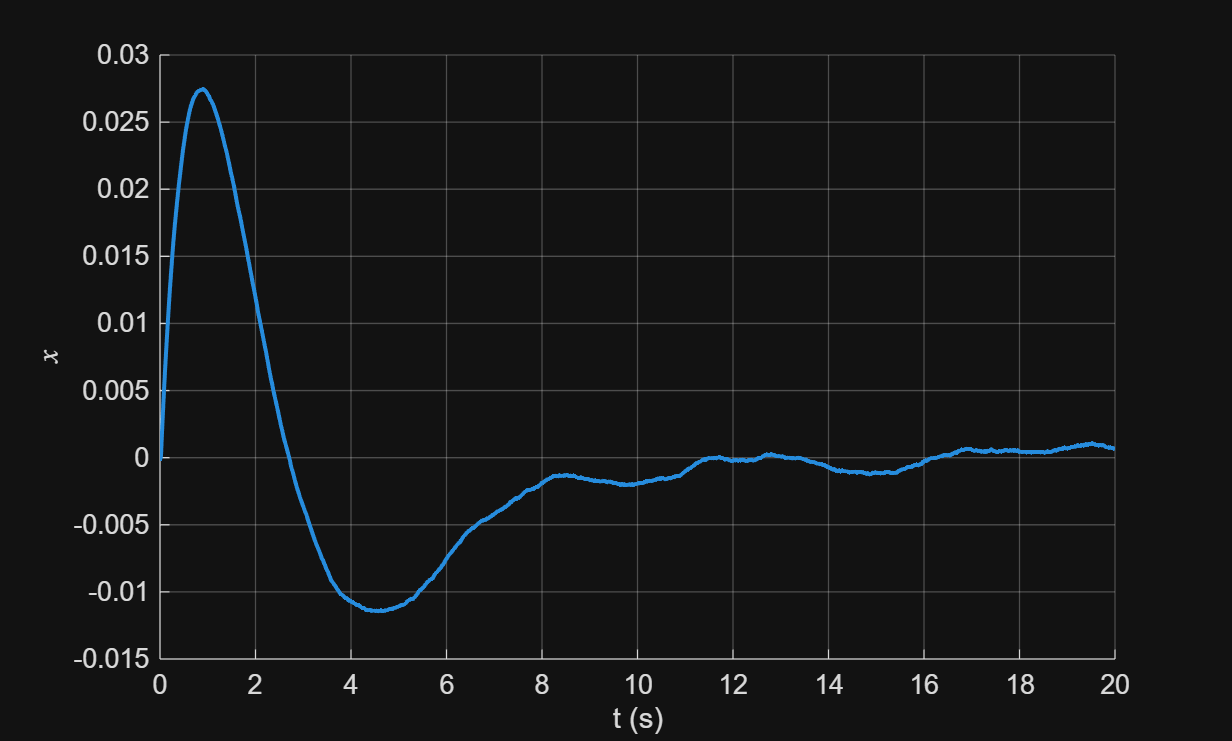

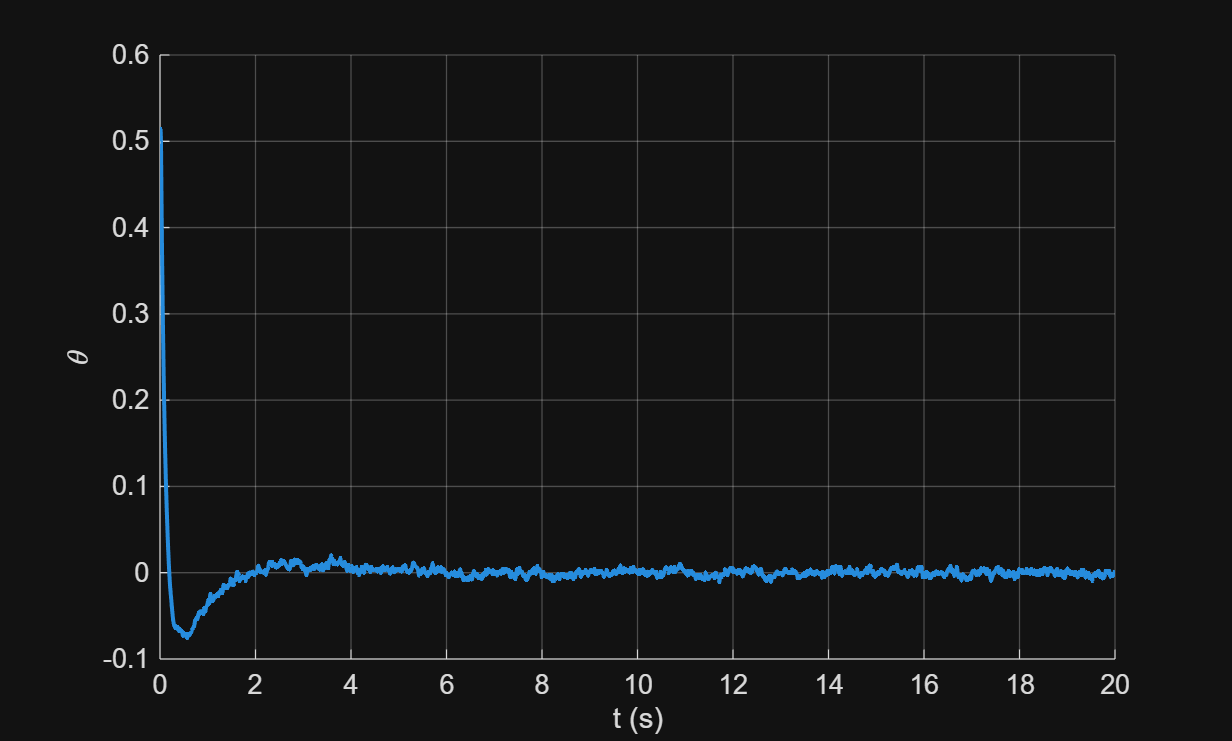

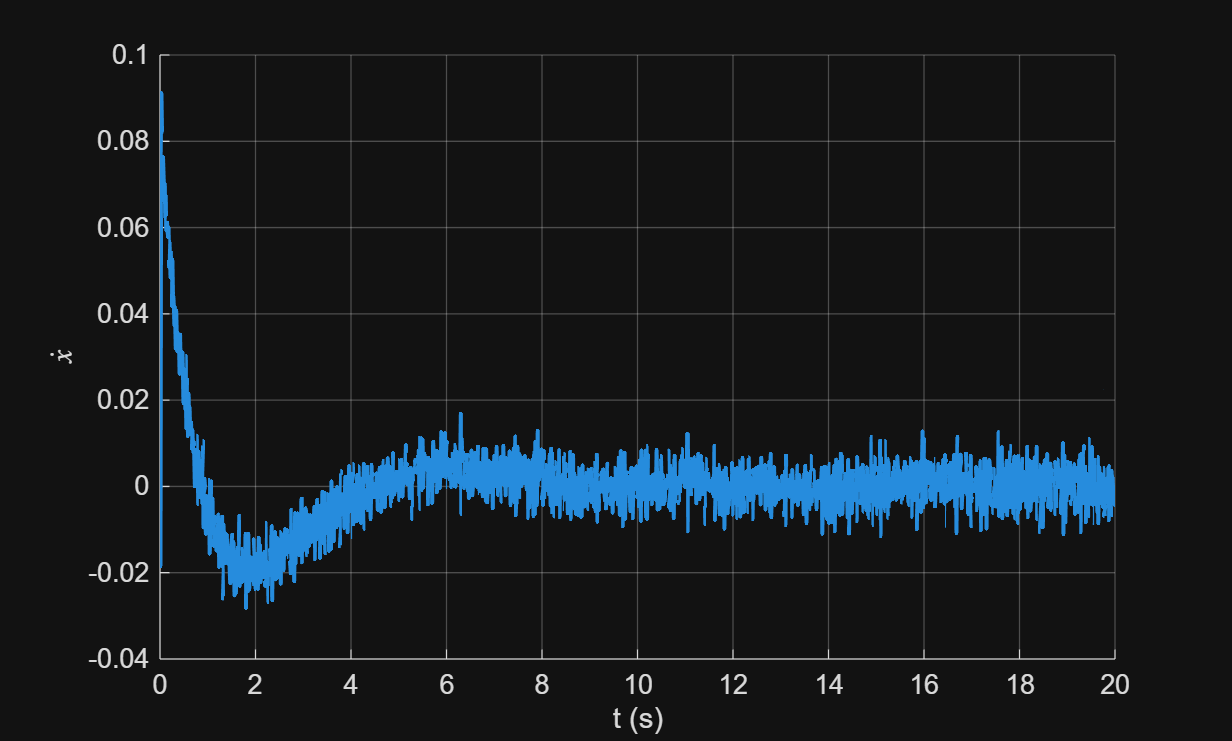

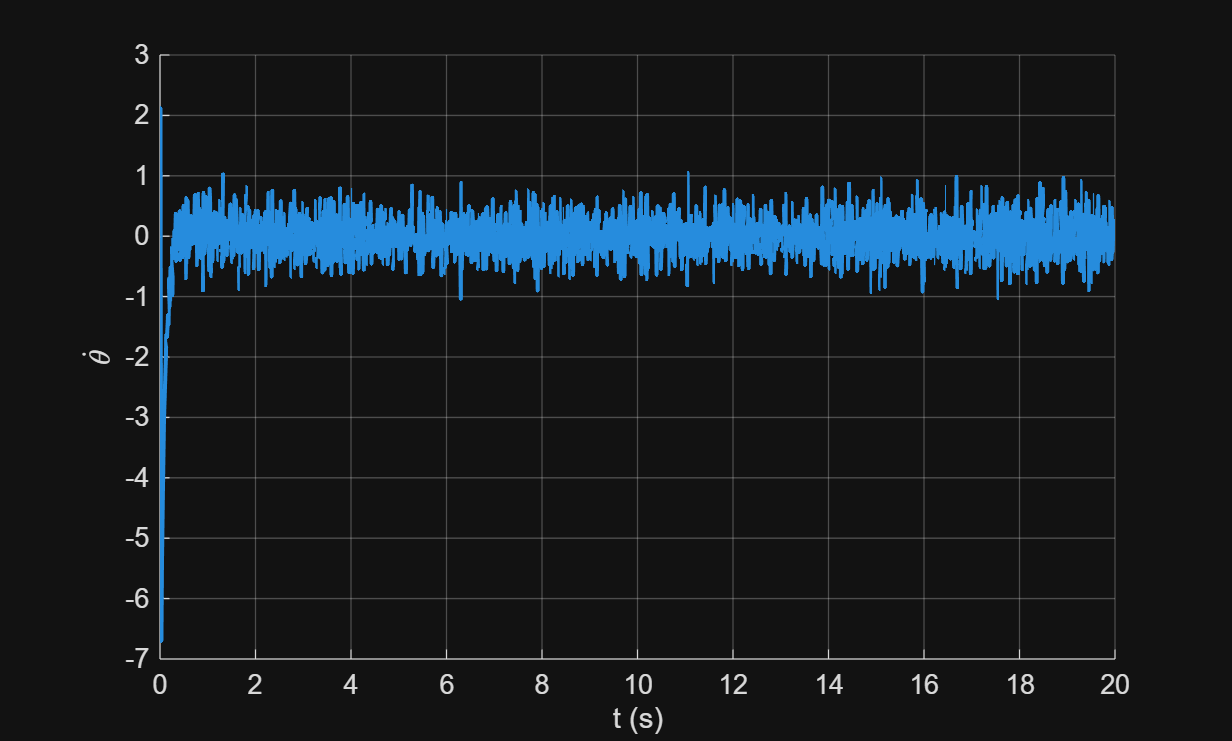

clear
close
clc
rng(1)

syms M_c m g l r b_v real
syms x(t) theta(t) x_dot theta_dot x_ddot theta_ddot
syms tau tauL tauR

params = [M_c; m; g; l; r];
values = [10; 5; 9.82; 0.03; 0.085];

% Large balancer
%values = 10*[0.3; 0.1; 9.82/10; 0.05; 0.025; 0.01; 3.71*10^-5; 3.75*10^-7];
%values = [5; 1; 9.82; 0.3; 0.075; 0.01; 3.71*10^-5; 3.75*10^-7];
%values = [5; 10; 9.82; 0.3; 0.075; 0; 0; 0];

% Differentiated variables
vars_diff = [diff(x,t,2); diff(x); x; diff(theta,t,2); diff(theta); theta];

% Inverse pendulum mass dynamics
posx_m = l*sin(theta) + x;
accx_m = diff(posx_m, t, 2); % second derivative

% Force required to accelerate the pendulums mass
F_pend = m*accx_m;

% The force applied on the "cart" is
% the force generated by the motors
% minus the reaction force from the pendulum mass (x component)
F_mot = (tauL + tauR)/r;
eq1 = M_c*diff(x,t,2) == F_mot - F_pend;

% Considering the load to be a point mass
% and tau is motor reaction torque
eq2 = m*l^2*diff(theta,t,2) == m*g*l*sin(theta) - m*l*diff(x,t,2)*cos(theta) - (tauL + tauR);

% Collect terms
eq1 = collect(lhs(eq1) - rhs(eq1), vars_diff);
eq2 = collect(lhs(eq2) - rhs(eq2), vars_diff);

% Express symbolically
syms x theta
vars_sym = [x_ddot; x_dot; x; theta_ddot; theta_dot; theta];
eq1 = subs(eq1, vars_diff, vars_sym);
eq2 = subs(eq2, vars_diff, vars_sym);

% Nonlinear model
[M, rest] = equationsToMatrix([eq1; eq2], [x_ddot; theta_ddot]);
accels = M \ rest;

f = formula([x_dot;
             theta_dot;
             accels(1);
             accels(2)]);

% Use values as the "correct" model
model = subs(f, formula(params), values);
pendulum_dynamics = matlabFunction(model, 'Vars', {x, theta, x_dot, theta_dot, tauL, tauR});

% Linearized model
op_state = [0; 0; 0; 0];
op_u = [0; 0];

n_size = 4;
m_size = 2;
n_aug = 1;

x_sym = formula([x; theta; x_dot; theta_dot]);
u_sym = formula([tauL; tauR]);

A_sym = jacobian(f, x_sym);
B_sym = jacobian(f, u_sym);

A_lin = subs(A_sym, [x_sym; u_sym], [op_state; op_u]);
B_lin = subs(B_sym, [x_sym; u_sym], [op_state; op_u]);

A = double(subs(A_lin, formula(params), values));
B = double(subs(B_lin, formula(params), values));
C = eye(4);

Ts = 0.01;

sys = ss(A,B,C,0);
dsys = c2d(sys, Ts);
Ad = dsys.A;
Bd = dsys.B;

Obsv = rank(obsv(sys));
Cont = rank(ctrb(sys));

% Weights
Qi = 10;

Qx = [100, 0, 0, 0;
      0, 100, 0, 0;
      0, 0, 1, 0;
      0, 0, 0, 1];

Qu = [1, 0;
      0, 1];

% integral action can only act in steady state.
% i.e velocities are zero. In this case its only possible
% to integrate position for some reason.
Ci = [1, 0, 0, 0];

Qx_aug = blkdiag(Qx, Qi);

Ad_aug = [Ad, zeros(n_size,n_aug);
          Ts*Ci, eye(n_aug)];

Bd_aug = [Bd;
          zeros(n_aug,m_size)];

[Kd,~,~] = dlqr(Ad_aug, Bd_aug, Qx_aug, Qu);

% Check stability
eig(Ad_aug - Bd_aug*Kd);

% Simulate nonlinear system
t_end = 20;
T = 0:Ts:t_end;
P0 = 1*eye(n_size + n_aug);
x0 = zeros(n_size + n_aug, 1);
x0(2) = 0.5; % set initial states

xd = x0;
xd_int = 0;
yd = zeros(n_size + n_aug, 1);
xd_filtered = x0;
Pd = P0;
ud_prev = zeros(m_size, 1);

x = x0;
x_int = 0;
y = zeros(n_size + n_aug, 1);
x_filtered = x0;
P = P0;
u_prev = zeros(m_size, 1);

Q = 0.01*eye(n_size + n_aug);
H = eye(n_size + n_aug);
R = blkdiag(0.05*eye(n_size), zeros(n_aug, n_aug)); % integral states are not sensors

% Assume zero mean measurement noise
% rough values:
sigma = [0.001; 0.001; 0.001; 0.1];

t_traj = [];
t_meas = [];
X = [];
X_filtered = [];
P_filtered = [];
Y = [];
U = [];

Xd = x0.';
Ud = u_prev.';

for k = 1:length(T)-1

    % Compute noise, use in linear and nonlinear model
    n = normrnd(0, sigma);
    
    % Linear simulator
    yd(1:4) = xd(1:4) + n;      % take measurement, add simulated noise
    xd_int = xd_int + yd(1)*Ts;   % integrate position
    yd(5) = xd_int;

    [xd_filtered, Pd] = kalmanFilter(yd, H, R, xd_filtered, Pd, Ad_aug, Q, Bd_aug, ud_prev);
    ud = -Kd*xd_filtered;
    ud_prev = ud;

    % Simulate system
    xd = Ad_aug*xd + Bd_aug*ud;
    
    Xd = [Xd; xd.'];
    Ud = [Ud; ud.'];

    % Nonlinear simulator
    % Integrate nonlinear system over [T(k), T(k+1)] with constant u
    ode = @(t,x) pendulum_dynamics(x(1), x(2), x(3), x(4), u_prev(1), u_prev(2));
    [tk, xk] = ode45(ode, [T(k), T(k+1)], x(1:4)); % Simulate from "true" state
    x = xk(end,:).';
    y = x + n;
    y(1:4) = x(1:4) + n;      % take measurement, add simulated noise
    x_int = x_int + y(1)*Ts;   % integrate position
    y(5) = x_int;
    
    % Predict and filter from "x0"
    [x_filtered, Pd] = kalmanFilter(y, H, R, x_filtered, P, Ad_aug, Q, Bd_aug, u_prev);
    u = -Kd*x_filtered;
    u_prev = u;

    % Append trajectory
    t_traj = [t_traj; tk];
    X = [X; xk];
    
    % Store states
    t_meas = [t_meas; tk(1)];
    Y = [Y; y.'];
    U = [U; repmat(u,[1, length(tk)]).'];
    X_filtered = [X_filtered; x_filtered.'];

end

%% Plots
states = ["$x$"; "$\theta$"; "$\dot{x}$"; "$\dot{\theta}$"];
for i = 1:size(X,2)
    % Interpolate linear model to nonlinear size
    % for error comparison
    Xd_lerp = interp1(T, Xd(:,i), t_traj);
    figure;
    hold on
    plot(t_traj, X(:,i), 'LineWidth', 1.5);
    %plot(T, Xd(:,i), 'LineWidth', 1.5, 'Color', 'r');
    % relative error
    % plot(t_traj, (X(:,i) - Xd_lerp), 'LineWidth', 1.5, 'Color', 'y')
    % scatter(t_meas, Y(:,i), 5, 'filled');
    % plot(t_meas, X_filtered(:,i), 'LineWidth',1.5);

    xlabel('t (s)');
    ylabel(states(i),'Interpreter','latex');
    grid on;
    hold off
end

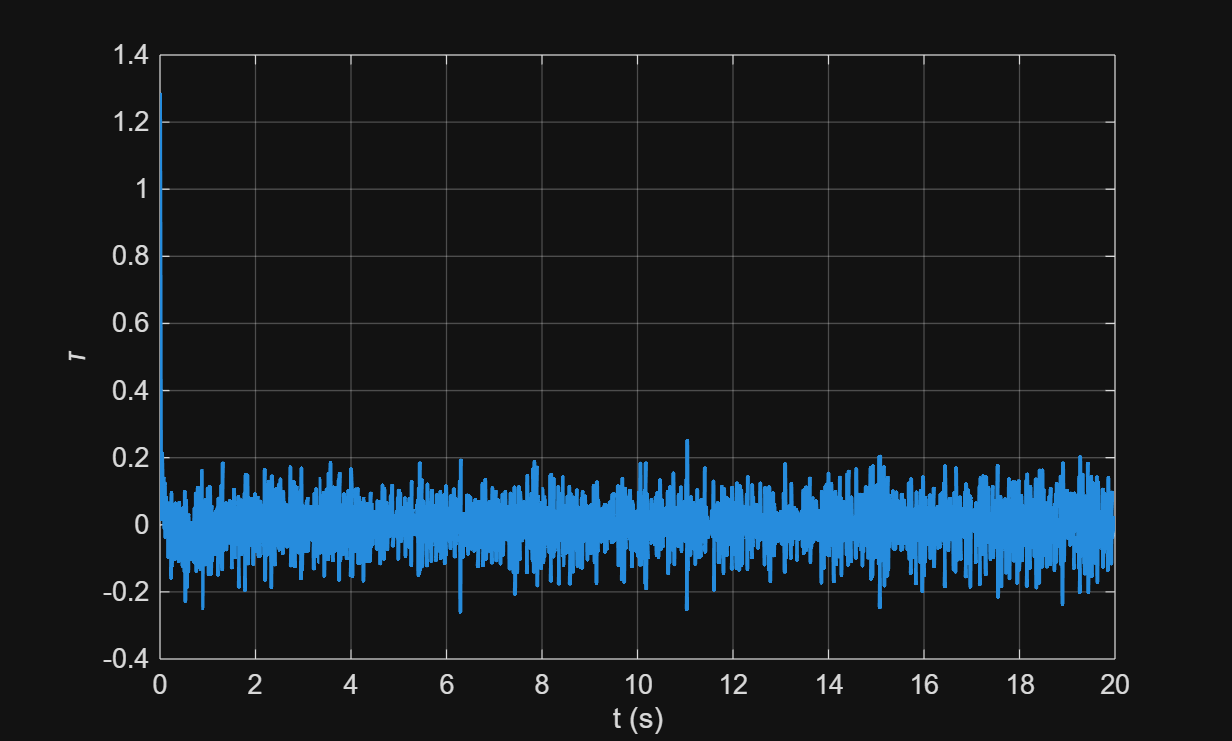


figure(2)
plot(t_traj, U(:,1), 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;


figure(3)
plot(t_traj, U(:,2), 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;

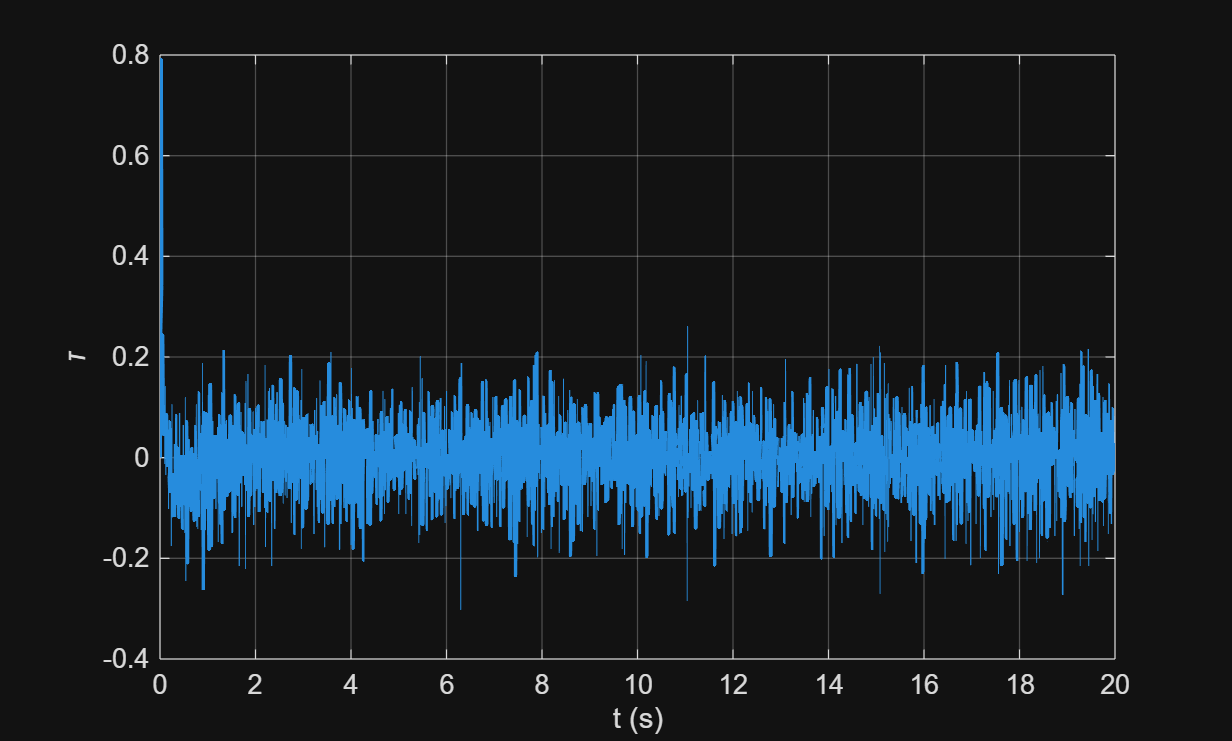


figure(3)
plot(T, Ud(:,1), 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;


figure(3)
plot(T, Ud(:,2), 'LineWidth', 1.5);
xlabel('t (s)');
ylabel('\tau');
grid on;


commat(Ad_aug)

ans =     '1, -0.000246506, 0.01, -8.20345e-07, 0,
     0, 1.02465, 0, 0.010082, 0,
     0, -0.0495028, 1, -0.000246506, 0,
     0, 4.95028, 0, 1.02465, 0,
     0.01, 0, 0, 0, 1,'


commat(Bd_aug)

ans =     '0.000226254, 0.000226254,
     -0.0187038, -0.0187038,
     0.0454037, 0.0454037,
     -3.75605, -3.75605,
     0, 0,'


commat(Kd)

ans =     '-1.78679, -2.13372, -2.23291, -0.166708, -0.383698,
     -1.78679, -2.13372, -2.23291, -0.166708, -0.383698,'
